# Orientation Dynamics

In this file, we will think about the dynamics of orientation in 3D space. This file follows closely the presentation of dynamics in Featherstone. 

clear; clc; close all;

## Equations of Motion

The typical robotic equations of motion are expressed $D(q) \ddot{q} + C(q, \dot{q})\dot{q} + G(q) = \tau$. This implies that the generalized velocity coordinates are the derivative of the generalized position coordinates, and assumes a specific form on the coriolis and gravity matrices. In general holonomic constraints, orientation representation, or other choices may cause the velocity variables to have a different dimension from (or just not be the derivative of) the position variables. In this case, the dynamic equations become:


$$\left[ \matrix{ \dot{q} \cr \dot{\alpha}}\right] = \left[ \matrix{ Q(q) \alpha \cr H(q)^{-1} (\tau - C(q, \dot{q})) }\right]$$


where $\alpha$ is the velocity variables, $H$ is the generalized inertia matrix (such that kinetic energy is $K = \frac{1}{2} \dot{q}^\top H\dot{q}$ ), $C$ is the bias force (generalized force required for zero acceleration), and $Q$ maps velocities to rates of change of position coordinates, necessary such that $\dot{q}$ can be integrated to give position. 

To derive these equations of motion, it is often desirable to express motion of rigid bodies in terms of spatial velocities (introduced in previous section) and spatial forces, and derive equations in terms of these quantities. We will do so next. First, we introduce a general rigid body which we will use to examine these properties. 

m = 1;          % Mass
Ixx = 0.1;      % Body x inertia (about CoM)
Iyy = 0.2;      % Body y inertia (about CoM)
Izz = 0.05;     % Body z inertia (about CoM)

## Spatial Motion and Spatial Force Vectors

The notion of 'twist' from the kinematics section is captured by the concept of a spatial motion vector, $v \in M^6$. Given a body moving in space, and a coordinate frame $O$, the spatial motion of $B$ relative to $O$ is given by $v = \left[\matrix{\omega \cr \nu}\right]$, where $\omega$ is the angular velocity of the body in the $O$ frame, and $\nu$ is the velocity of the point on $B$ coincident with the origin of $O$, expressed in the $O$ frame. The velocity of a point on the body is then given by $v_p = \nu + \omega \times r_p$. 

Dual to a spacial motion vector is the concept of a spatial force vector (or wrench), which is $f = \left[\matrix{n_O \cr f}\right] \in F^6$, where $n_O$ is the moment about the origin of $O$, and $f$ is the applied force. 

A few notes: the convention used is 'angular over linear', where angular components come first, and linear components come second. Second, one can distinguish between 'line vectors', which acts along an axis in space, and a 'free vector' whose action does not depend on where it is applied. Angular components are free vectors, and vectors with linear and angular components orthogonal are line vectors. Finally, $M^6$ and $F^6$ are dual, and have a scalar product defined on them, $m^\top f$, giving the instantaneous power delivered by the wrench. 

## Coordinate Transforms for Spatial Vectors

As discussed in the previous file on kinematics, spatical motion vectors transform coordinate systems via the adjoint operator. As suggestive by the duality between $M^6$ and $F^6$, wrenches transform according to the transpose of the adjoint. Given coordinate frames $A$ and $B$, 


$$^B X_A = \left[ \matrix{E & 0 \cr -E r\times & E}\right] \quad\quad ^B X_A^* = \left[ \matrix{E & -E r\times \cr 0 & E}\right]$$
  

where $E$ is the rotation matrix from $A$ to $B$, $r$ is the translation from $A$ to $B$, and $\times$ defines the operator $(r\times) (v) = r \times v$. Note that $*$ does not denote a pure transpose, but rather an 'adjoint transpose', where only the blocks are moved, the blocks are not transposed. Each of these matrices is has inverses:


$$^A X_B = \left[ \matrix{E^\top & 0 \cr r \times E^\top & E^\top}\right] \quad\quad ^B X_A^* = \left[ \matrix{E^\top & r \times E^\top \cr 0 & E^\top}\right]$$
  

## Differentiation of Spatial Vectors

Differentiation requires definition of a cross product (recall $\dot{r} = \omega \times r$ for differentiating a rotating unit vector). To preserve these kinds of properties, we define


$$v\times = \left[\matrix{\omega \cr \nu}\right] \times = \left[\matrix{\omega \times & 0 \cr \nu\times & \omega \times}\right] \quad \quad v ~\times^* = \left[\matrix{\omega \cr \nu}\right] \times^* = \left[\matrix{\omega \times & \nu\times \cr 0 & \omega \times}\right] = (-v\times)^\top$$
 

where $\times^*$ defines the dual cross product, used to operate on elements of $F^6$, so $v \times m$ is defined for $v, m \in M^6$, and $v ~\times^* f$ is defined for $f \in F^6$. 

Now, we can define differentiation in moving coordinates. If $m \in M^6, f\in F^6$ are defined relative to a moving frame $A$, then 


$$^A\left(\frac{dm}{dt}\right) = \frac{d^A m}{dt} + v_A \times m \quad \quad ^A\left(\frac{df}{dt}\right) = \frac{d^A f}{dt} + v_A \times^* f$$
 

where $\frac{d^A}{dt}$ represents componentwise differentiation in the $A$ frame. To distinguish these derivatives we use $^A\dot{v}=^A\left(\frac{dv}{dt}\right)$ and $^Av^\circ = \frac{d^A(\cdot)}{dt}$. We can also differentiate adjoint operators:

$\frac{d}{dt} B^X_A = ^B(v_A - v_B) \times {^BX}_A$. 

## Acceleration, Momentum, and Equations of Motion

Spatial acceleration is defined as


$$a = \frac{d}{dt}v = \left[\matrix{\dot{\omega} \cr \dot{\nu}}\right]$$
 

Suprisingly, this term may feel as though it is missing coriolis terms, ect. Spatial acceleration is a property of the body as a whole, not of individual body-fixed points. Since $\nu$ measures the 'flow rate' of points on the body through a point in space, $\dot{\nu}$ is the rate of change of this flow, not the acceleration of individual points on the rigid body. If the flow is constant, $\dot{\nu}$ will be zero even if each individual point is accelerating. Note that both spatial velocity and acceleration have relative quantities given by differences:


$$v_{rel} = v_2 - v_1 \quad \quad a_{rel} = a_2 - a_1$$


Spatial momentum can be captured in much the same way. About the center of mass, we have $h_c = \left[\matrix{I_C \omega \cr m \nu}\right]$and about the origin, $h_O = \left[\matrix{I & r_{OC}\times \cr 0 & I}\right]h_c$. Defining spatial inertia $I_c = \left[\matrix{I_c & 0 \cr 0 & mI}\right]$, we can define $h_c = Iv$ and $h_O =\left[\matrix{I & c\times \cr 0 & I}\right] I_cv_c=\left[\matrix{I & c\times \cr 0 & I}\right]I_c\left[\matrix{I & 0 \cr c\times^\top & I}\right]v_O$. This implies that $I_O = \left[\matrix{I_c + mc \times c^\top & mc \times \cr m c\times ^\top & mI}\right]$. Inertia matrices can be expressed as dyads, which gives rise to thier rate of change: $\frac{d}{dt} I = v \times^* I + I v\times$. Note that the rate of change of the inertia matrix is a property only of the motion of the body (interpret this as the inertia being fixed in a body-attached frame). 

With acceleration, inertia, and momenum defined, we can write down the equations of motion for a rigid body:


$$f = \frac{d}{dt}Iv = Ia + (v\times^*I + Iv\times)v = Ia + v\times^*Iv=Ia + p$$


Defining $\phi = I^{-1}$, the 'inverse inertia', the equation can also be written: $a = \phi f + b$. 

## Example: Floating Rigid Body

As a first example, lets compute the equations of motion for a floating rigid body. The approach will be to compute the dynamics in the body-aligned frame (frame fixed in space, instantaneously coincident with the body frame), and then move these computations into the world frame for integration?

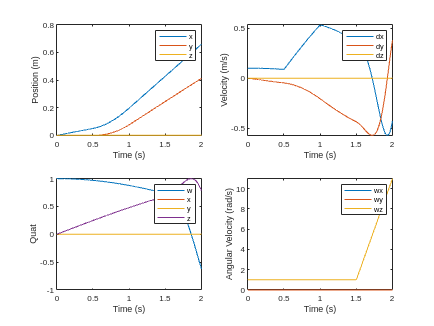

bIc = diag([Ixx, Iyy, Izz, m, m, m]);  % Inertia about the CoM, in the body frame

q0 = [1; 0; 0; 0];
p0 = [0; 0; 0];
v0 = [0; 0; 1; 0.1; 0; 0];
x0 = [q0; p0; v0];

f0 = [0;0;0;1;0;0];
f1 = [0;0;1;0;0;0];

% Forcing function, which will be applied in the body frame
f = @(x, t) f0 * (t > 0.5 & t <= 1) + f1 * (t > 1.5 & t <= 2);
% f = @(x, t) f1 * (t > 0 & t <= 1) + f0 * (t > 1.5 & t <= 2);
% f = @(x, t) zeros(6, 1);

% Integration parameters
dt = 0.001;
T = 2;
tpts = linspace(0, 2, floor(T / dt) + 1);
x = integrate_dynamics(x0, f, tpts, bIc);

% Visualize Results
q = x(1:4, :);
p = x(5:7, :);
v = x(8:13, :);

figure()
subplot(2,2,1)
plot(tpts, p)
legend('x', 'y', 'z')
xlabel('Time (s)')
ylabel('Position (m)')
subplot(2,2,2)
plot(tpts, v(4:6, :))
legend('dx', 'dy', 'dz')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
subplot(2,2,3)
plot(tpts, q)
legend('w', 'x', 'y', 'z')
xlabel('Time (s)')
ylabel('Quat')
subplot(2,2,4)
plot(tpts, v(1:3, :))
legend('wx', 'wy', 'wz')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')

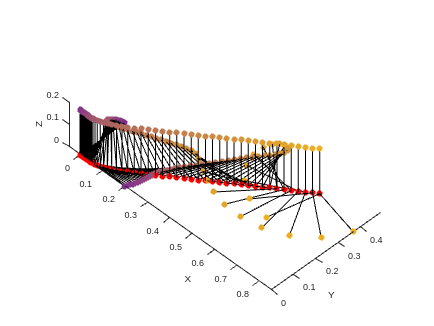

fh = figure();

N = 50;
dN = floor(numel(tpts) / N);
t_resamp = tpts(1:dN:end);
x_resamp = x(:, 1:dN:end);
q = x_resamp(1:4, :);
p = x_resamp(5:7, :);
v = x_resamp(8:13, :);
for ii = 1:length(t_resamp)
    g = g_qp(quat_inv(q(:, ii)), p(:, ii));
    plot_gframe_traj(fh, g, ii / length(t_resamp))
end

##  Articulated Bodies

Finally, we will be concerned with a rigid body with joints. 

## Helper Functions

### Step Dynamics

function x = step_dynamics(x, f, I, dt)
% Assume force is applied in the local frame here
q = x(1:4) / norm(x(1:4)); % quaternion representing orientation
p = x(5:7);                % Position vector in O coordinates
v = x(8:13);               % generalized velocity vector in local frame

a = I \ (f - m_cross_d(v) * (I*v)); % Acceleration (local frame)

g_m = g_qp(q, p);

% Euler integration scheme
v_p = v + dt * a;          % new spacial velocity

dq = dotq(q, v(1:3));     % Rate of change of quaternion
dp = v(4:6);              % Rate of change of position

q_p = q + dt * dq;
q_p = q_p / norm(q_p);           % New quaternion
p_p = p + dt * g_m.R' * dp;      % New position (transform velo into world-aligned frame)

g_p = g_qp(q_p, p_p);
v_p = bXa(g_p) * aXb(g_m) * v_p; % Move new velocity to new body coord frame.

x = [q_p; p_p; v_p];
end

### Integrate Dynamics Open Loop

function x = integrate_dynamics(x0, f, tpts, bIc)
x = zeros(size(x0, 1), numel(tpts));
x(:, 1) = x0;
for ii = 2:numel(tpts)
    t_m = tpts(ii - 1);
    t_p = tpts(ii);
    dt = t_p - t_m;
    x_m = x(:, ii - 1);
    x(:, ii) = step_dynamics(x_m, f(x_m, t_m), bIc, dt);
end
end